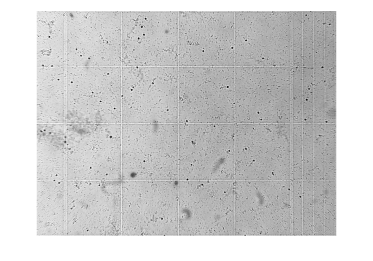

clear all
I=imread("S2_1.bmp");

I=rgb2gray(I);
imshow(I,[])

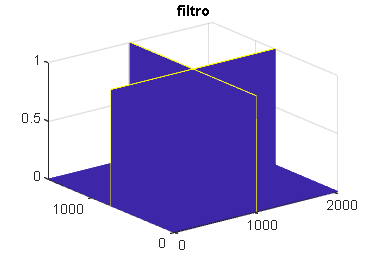


If=fft2(I);
%imshow(log(1+abs(If)),[])
If1=fftshift(If);
%imshow(log(1+abs(If1)),[])

[P , Q]=size(If); %p filas q columbas
D=zeros(P,Q);
Do=1; %humbral de frecuencia
p2 = round(P/2);
q2 = round(Q/2);
D([p2-Do p2+Do],1:end) = 1 ;
D(1:end,[q2-Do q2+Do]) = 1;
H = D;
mesh(H)
title("filtro")


H1=fftshift(H);
%mesh(H1)

Bf=If.*H1;
%imshow(log(1+abs(Bf)),[])
I2=ifft2(Bf); 
%I2 = escalar(I2,255);
imshow(I2,[])

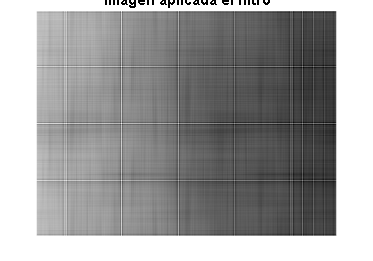

title("imagen aplicada el filtro")

%I5 = double(escalar(I,255));
imshow(double(I)-I2,[]);

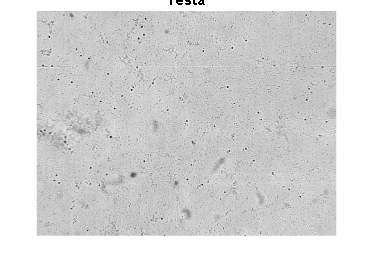

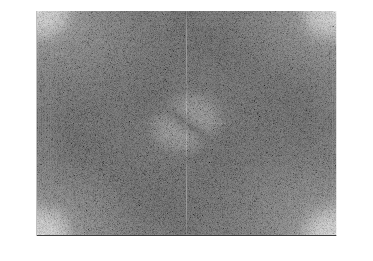

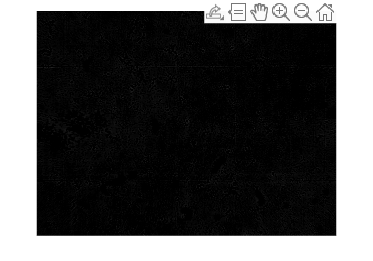

title("resta")